    %  Supporting functions
    
    
    % Function to make everything at least water in simulation
    function [density, sound_speed] = apply_min_limits(matrix, min_value)
    matrix(matrix < min_value) = min_value;
    density = matrix;
    end
    
    
    % Function to set medium properties if in water (no skull)
    function [medium] = create_water_medium(Nx, Ny, Nz, temp, aWater, y_water)
    medium.density = waterDensity(temp) * ones(Nx, Ny, Nz); % Water density
    medium.sound_speed = waterSoundSpeed(temp) * ones(Nx, Ny, Nz); % Water sound speed
    medium.alpha_coeff = aWater * ones(Nx, Ny, Nz); % Water attenuation coefficient
    medium.alpha_power = y_water; % Water power law exponent
    end
    
    
    % Function to set medium properties if using ct (with skull)
    function [medium] = create_tissue_medium(Nx, Ny, Nz, density, sound_speed, alpha_coeff, y)
    medium.density = density; % Tissue density
    medium.sound_speed = sound_speed; % Tissue sound speed
    medium.alpha_coeff = alpha_coeff; % Tissue attenuation coefficient
    medium.alpha_power = y; % Tissue power law exponent
    end
    
    
    % Function to plot a specific plane slice with contours
    function plot_slicePost(matrix, matrix_t_1, matrix_t_2, matrix_target, slice_range, plane_type)
    figure;
    for i = slice_range
    midX = i;
    midY = i;
    midZ = i;
    % Extract the slices for the specified plane
    if strcmp(plane_type, 'XY')
    slice = squeeze(matrix(:, :, midZ));
    slice_tr1 = squeeze(matrix_t_1(:, :, midZ));
    slice_tr2 = squeeze(matrix_t_2(:, :, midZ));
    slice_tar = squeeze(matrix_target(:, :, midZ));
    title_text = ['XY Plane ', num2str(i)];
    xlabel_text = 'Y';
    ylabel_text = 'X';
    elseif strcmp(plane_type, 'XZ')
    slice = squeeze(matrix(:, midY, :));
    slice_tr1 = squeeze(matrix_t_1(:, midY, :));
    slice_tr2 = squeeze(matrix_t_2(:, midY, :));
    slice_tar = squeeze(matrix_target(:, midY, :));
    title_text = ['XZ Plane ', num2str(i)];
    xlabel_text = 'Z';
    ylabel_text = 'X';
    elseif strcmp(plane_type, 'YZ')
    slice = squeeze(matrix(midX, :, :));
    slice_tr1 = squeeze(matrix_t_1(midX, :, :));
    slice_tr2 = squeeze(matrix_t_2(midX, :, :));
    slice_tar = squeeze(matrix_target(midX, :, :));
    title_text = ['YZ Plane ', num2str(i)];
    xlabel_text = 'Z';
    ylabel_text = 'Y';
    end
    
    
    % Plot the plane
    ax1 = axes;
    im = imagesc(ax1,slice);
    im.AlphaData = 1;
    axis equal;
    % title(title_text);
    % xlabel(xlabel_text);
    % ylabel(ylabel_text);
    ax2 = axes;
    im1 = imagesc(ax2, slice_tr1);
    im1.AlphaData = 0.5;
    axis equal;
    linkaxes([ax1, ax2]);
    ax2.Visible = 'off';
    ax2.XTick = [];
    ax2.YTick = [];
    hold(ax2,'on')
    contour(slice_tr2, 1, 'LineColor', 'red', 'LineWidth', 1);
    contour(slice_tar, 1, 'LineColor', 'g', 'LineWidth', .1);
    colormap(ax1, 'gray');
    clim(ax1, [0,50]);
    colormap(ax2, 'hot');
    %set the axes and colorbar position
    % set([ax1,ax2],'Position',[.17 .11 .685 .815]);
    % cb1 = colorbar(ax1,'Position',[.05 .11 .0675 .815]);
    % cb2 = colorbar(ax2,'Position',[.88 .11 .0675 .815]);
    % Label the colorbars
    % cb1.Label.String = 'Signal Intensity (housefield units)';
    % cb2.Label.String = 'Pressure (Pa)';
    hold(ax1,'off')
    hold(ax2,'off')
    pause(0.001);
    ax1.Visible = 'off';
    ax1.XTick = [];
    ax1.YTick = [];
    end
    end
    
    
    % Function to plot a specific plane slice with contours
    function plot_slice(matrix, matrix_t_1, matrix_t_2, matrix_target, slice_range, plane_type)
    figure;
    for i = slice_range
    midX = i;
    midY = i;
    midZ = i;
    % Extract the slices for the specified plane
    if strcmp(plane_type, 'XY')
    slice = squeeze(matrix(:, :, midZ));
    slice_tr1 = squeeze(matrix_t_1(:, :, midZ));
    slice_tr2 = squeeze(matrix_t_2(:, :, midZ));
    slice_tar = squeeze(matrix_target(:, :, midZ));
    title_text = ['XY Plane ', num2str(i)];
    xlabel_text = 'Y';
    ylabel_text = 'X';
    elseif strcmp(plane_type, 'XZ')
    slice = squeeze(matrix(:, midY, :));
    slice_tr1 = squeeze(matrix_t_1(:, midY, :));
    slice_tr2 = squeeze(matrix_t_2(:, midY, :));
    slice_tar = squeeze(matrix_target(:, midY, :));
    title_text = ['XZ Plane ', num2str(i)];
    xlabel_text = 'Z';
    ylabel_text = 'X';
    elseif strcmp(plane_type, 'YZ')
    slice = squeeze(matrix(midX, :, :));
    slice_tr1 = squeeze(matrix_t_1(midX, :, :));
    slice_tr2 = squeeze(matrix_t_2(midX, :, :));
    slice_tar = squeeze(matrix_target(midX, :, :));
    title_text = ['YZ Plane ', num2str(i)];
    xlabel_text = 'Z';
    ylabel_text = 'Y';
    end
    % Plot the selected plane slice
    imagesc(slice);
    title(title_text);
    xlabel(xlabel_text);
    ylabel(ylabel_text);
    colormap('gray');
    % Set color limits
    clim([0, 50]);
    % Add contours for the transducers and target (if available)
    hold on;
    contour(slice_tr1, 1, 'LineColor', 'r', 'LineWidth', 1);
    contour(slice_tr2, 1, 'LineColor', 'g', 'LineWidth', 0.1);
    if ~isempty(slice_tar)
    contour(slice_tar, 1, 'LineColor', 'b', 'LineWidth', 0.1);
    end
    hold off;
    pause(0.001);
    end
    end
    
    
    % Function to calculate the transducer positon to target the point while
    % being a focal length away
    function [eul_deg_2, transducer_loc, target_loc, eul_deg, R] = calculateRotTrans(target, transducer_est_loc, voxel_size, focal_length)
    p0 = target;
    p1 = transducer_est_loc;
    v = p0-p1;
    % Let's define si and theta in such a way that.
    r = norm(v);
    si = atan2(v(3),v(1))
    theta = atan2(v(2),sqrt(v(1).^2+v(3).^2))
    v = [r*cos(si)*cos(theta), r*sin(theta), r*sin(si)*cos(theta)];
    j = [cos(si)*cos(theta), sin(theta), sin(si)*cos(theta)];
    % Correspond to j vector you can also find orthonormal vector to j
    i = [sin(si), 0, -cos(si)];
    k = [cos(si)*sin(theta), -cos(theta), sin(si)*sin(theta)];
    % Rotation matrix;
    m = [i',j',k'];
    % You can use MATLAB inbuilt function to convert rotation matrix to Euler system
    eul = rotm2eul(m);
    eul_deg = rad2deg(eul)
    
    
    % Calculate the rotation matrix to align the initial z-axis to the direction of the target
    initial_orientation = [0, 0, 1]; % Positive Z direction
    direction = v / norm(v); % Normalize the target direction
    % Calculate the rotation matrix to align the transducer with the target direction
    R = rotation_matrix_from_vectors(initial_orientation, direction)
    % You can use MATLAB inbuilt function to convert rotation matrix to Euler system
    eul_2 = rotm2eul(R);
    eul_deg_2 = rad2deg(eul_2)
    
    
    % Apply the rotation to the transducer location
    Atransducer_loc = (R * (p1 - p0)')' + p0;
    
    
    % Apply the rotation to the transducer location
    target_loc = (R * (p0 - p1)')' + p1;
    % Transducer point
    far_target_distance = focal_length/voxel_size;
    distance = sqrt((p1(1) - p0(1))^2 + (p1(2) - p0(2))^2 + (p1(3) - p0(3))^2);
    ratio = far_target_distance/distance;
    diff_t = p1-p0;
    dis_t = diff_t*ratio;
    transducer_loc = round(dis_t + p0);
    new_distance = sqrt((transducer_loc(1) - p0(1))^2 + (transducer_loc(2) - p0(2))^2 + (transducer_loc(3) - p0(3))^2);
    C = cross(p0, transducer_loc)
    D = dot(p0, transducer_loc);
    NP0 = norm(p0); % used for scaling
    if ~all(C==0) % check for colinearity
    Z = [0 -C(3) C(2); C(3) 0 -C(1); -C(2) C(1) 0] ;
    R1 = (eye(3) + Z + Z^2 * (1-D)/(norm(C)^2)) / NP0^2; % rotation matrix
    else
    R1 = sign(D) * (norm(p1) / NP0); % orientation and scaling
    end
    R_deg = rad2deg(R1);
    eulXYZ = rotm2eul(R1,'XYZ');
    eulXYZ_deg = rad2deg(eulXYZ);
    end
    
    
    % Function to compute the rotation matrix from two vectors
    function R = rotation_matrix_from_vectors(A, B)
    % A and B are unit vectors, the initial and final direction vectors
    A = A / norm(A);
    B = B / norm(B);
    v = cross(A, B);
    c = dot(A, B);
    s = norm(v);
    kmat = [ 0 -v(3) v(2);
    v(3) 0 -v(1);
    -v(2) v(1) 0];
    R = eye(3) + kmat + kmat^2 * (1 - c) / s^2;
    end
    
    
    function [skull_data, ct_data, voxel_spacing] = DicomToVolume(dicom_folder, volume_name, z_start, z_end, missing_slices, plot)
    % Convert dicoms to voxelized medVol for plotting
    medVol = medicalVolume(dicom_folder);
    % Convert dicoms to 3D volume for simulation
    for i=z_start:z_end
    if i < 10
    filenumber = append('IMG000',int2str(i),'.dcm');
    elseif i < 100 && i > 9
    filenumber = append('IMG00',int2str(i),'.dcm');
    else
    filenumber = append('IMG0',int2str(i),'.dcm');
    end
    
    
    ct_data(:,:,i) = dicomread(filenumber);
    
    
    if(plot)
    imshow(ct_data(:,:,i),DisplayRange=[]);
    end
    end
    
    
    % Get voxel spacing / other info if needed here:
    info = dicominfo(filenumber);
    voxel_spacing = [info.PixelSpacing(1), info.PixelSpacing(2), info.SliceThickness];
    
    
    ct_data = ct_data(:,:,z_start:z_end);
    skull_data = medVol.Voxels(:,:,(z_start-missing_slices):(z_end-missing_slices));
    
    
    % Save both files for further analysis
    save(append(volume_name,'_CT_data.mat'),"skull_data","ct_data","voxel_spacing");
    end
    
    
    %% Resize CT data to have cube voxels (if needed)
    
    
    function [resized_CT, resized_skull, voxel_size] = ResizeCT(ct_data, voxelized_skull, voxel_spacing, volume_name)
    
    
    % Permute voxzelized_skull (for some reason X and Y are switched)
    voxelized_skull_p = permute(voxelized_skull,[2,1,3]);
    
    
    % Find max spacing (to subsample to)
    voxel_size = max(voxel_spacing);
    
    
    % Determine resizing factor
    resize_factor_X = voxel_spacing(1)/voxel_size;
    resize_factor_Y = voxel_spacing(2)/voxel_size;
    resize_factor_Z = voxel_spacing(3)/voxel_size;
    
    
    % Resize CT and skull data
    resized_skull = imresize3(voxelized_skull_p,[(resize_factor_X*size(voxelized_skull_p,1)) ...
    (resize_factor_Y*size(voxelized_skull_p,2)) (resize_factor_Z*size(voxelized_skull_p,3))]);
    resized_CT = imresize3(ct_data,[(resize_factor_X*size(ct_data,1)) (resize_factor_Y*size(ct_data,2)) ...
    (resize_factor_Z*size(ct_data,3))]);
    
    
    % Save both files for further analysis
    save(append(volume_name,'_resized_CT_data.mat'),"resized_skull","resized_CT","voxel_size");
    
    
    end
    
    
    %% Put ct and skull into a larger FOV for transducer placement
    
    
    function [FOV_field_skull, FOV_field_ct] = PutIntoFOV(resized_CT, resized_skull, FOV, voxel_size)
    
    
    % Define FOV in voxel spacing
    FOV_field_skull = zeros(FOV(1)/voxel_size, FOV(2)/voxel_size, FOV(3)/voxel_size);
    FOV_field_ct = zeros(FOV(1)/voxel_size, FOV(2)/voxel_size, FOV(3)/voxel_size);
    % Determine extra space on all sides (same for ct and skull)
    ExtraX = size(FOV_field_skull,1) - size(resized_skull,1);
    ExtraY = size(FOV_field_skull,2) - size(resized_skull,2);
    ExtraZ = size(FOV_field_skull,3) - size(resized_skull,3);
    % Place the skull data into the center of the FOV
    FOV_field_skull((ExtraX/2):((ExtraX/2)+size(resized_skull,1)-1), (ExtraY/2):((ExtraY/2)+ ...
    size(resized_skull,2)-1), (ExtraZ/2):((ExtraZ/2)+size(resized_skull,3)-1)) = resized_skull;
    % Place the ct data into the center of the FOV
    FOV_field_ct((ExtraX/2):((ExtraX/2)+size(resized_CT,1)-1), (ExtraY/2):((ExtraY/2)+ ...
    size(resized_CT,2)-1), (ExtraZ/2):((ExtraZ/2)+size(resized_CT,3)-1)) = resized_CT;
    end
    
    
    %% Build transducer using make bowl
    
    
    function [transducer_origin_cut, transducerF_origin_cut, center_point] = BuildTransducer(radius, diameter)
    
    
    % Focus is equal to the radius of curvature
    focus = radius;
    
    
    % Define bounding box (big enough to allow rotation)
    Nx = (radius-1)*2;
    Ny = (radius-1)*2;
    Nz = (radius-1)*2;
    
    
    % Define Transducer center point and focal point (face up)
    center_point = [Nx/2,Ny/2,Nz/2];
    focal_point = [Nx/2,Nx/2,focus];
    
    
    % Build Transducer using makebowl function
    transducer = makeBowl([Nx, Ny, Nz], [center_point(1),center_point(2),center_point(3)] , radius, diameter, [focal_point(1),focal_point(2),focal_point(3)], 'RemoveOverlap', true);
    % Make transducer with focus stick
    transducer_focal = transducer;
    % add 3x3xfocuslength stick
    transducer_focal(Nx/2-1:Nx/2+1,Ny/2-1:Ny/2+1,Nz/2:Nz/2+focus-1) = 1;
    
    
    % Confirm transducer is in origin of bounding box
    % Find origin
    transducerOrigin = [-size(transducer, 1) / 2, -size(transducer, 2) / 2, -size(transducer, 3) / 2];
    % Apply translation to move transducer to the origin
    transducerF_at_origin = imtranslate(transducer_focal, transducerOrigin, "OutputView","full");
    transducer_at_origin = imtranslate(transducer, transducerOrigin, "OutputView","full");
    % Cut any region outside of transducer bounding box
    transducerF_origin_cut = transducerF_at_origin(1:(size(transducer_focal, 1)) , 1:(size(transducer_focal, 2)), 1:(size(transducer_focal, 3)));
    transducer_origin_cut = transducer_at_origin(1:(size(transducer, 1)) , 1:(size(transducer, 2)), 1:(size(transducer, 3)));
    end
    
    
    % Apply rotation and translation to transducer in FOV
    
    
    function [adjusted_transducer, adjusted_transducer_focal, translated_center_point] = ApplyRotationAndTranslation(transducer, transducer_focal, rotation, translation, FOV, voxel_size, center_point)
    
    % --- keep masks logical to save memory ---
    transducer       = logical(transducer);
    transducer_focal = logical(transducer_focal);
    
    % --- 1) Apply Rotation (same, nearest keeps masks) ---
    transducerFVolumeRotX = imrotate3(transducer_focal, rotation(1), [1 0 0], 'nearest', 'crop');
    transducerFVolumeRotY = imrotate3(transducerFVolumeRotX, rotation(2), [0 1 0], 'nearest', 'crop');
    transducerFVolumeRot  = imrotate3(transducerFVolumeRotY, rotation(3), [0 0 1], 'nearest', 'crop');
    
    transducerVolumeRotX = imrotate3(transducer, rotation(1), [1 0 0], 'nearest', 'crop');
    transducerVolumeRotY = imrotate3(transducerVolumeRotX, rotation(2), [0 1 0], 'nearest', 'crop');
    transducerVolumeRot  = imrotate3(transducerVolumeRotY, rotation(3), [0 0 1], 'nearest', 'crop');
    
    % --- 2) Build FOV with INTEGER dims and logical class ---
    volDims = ceil(FOV ./ voxel_size);               % integer [Nx Ny Nz]
    transducer_field  = false(volDims);              % logical saves RAM
    transducerF_field = false(volDims);
    
    % integer centering
    ExX = volDims(1) - size(transducerVolumeRot,1);
    ExY = volDims(2) - size(transducerVolumeRot,2);
    ExZ = volDims(3) - size(transducerVolumeRot,3);
    
    sx = 1 + floor(ExX/2);
    sy = 1 + floor(ExY/2);
    sz = 1 + floor(ExZ/2);
    
    % place into center
    transducer_field( sx:sx+size(transducerVolumeRot,1)-1, ...
                      sy:sy+size(transducerVolumeRot,2)-1, ...
                      sz:sz+size(transducerVolumeRot,3)-1) = logical(transducerVolumeRot);
    
    transducerF_field(sx:sx+size(transducerFVolumeRot,1)-1, ...
                      sy:sy+size(transducerFVolumeRot,2)-1, ...
                      sz:sz+size(transducerFVolumeRot,3)-1) = logical(transducerFVolumeRot);
    
    new_center_point = [center_point(1)+floor(ExX/2), ...
                        center_point(2)+floor(ExY/2), ...
                        center_point(3)+floor(ExZ/2)];
    
    % --- 3) Apply final (integer) translation ---
    translation = round(translation);
    adjusted_transducer       = imtranslate(transducer_field,   translation, "OutputView","same");
    adjusted_transducer_focal = imtranslate(transducerF_field, translation,  "OutputView","same");
    
    translated_center_point = new_center_point + translation;
    end
    
    
    
    % Plot the skull and transducer together
    function PlotFOV(FOV_field_skull, adjusted_transducer_focal_1, target, focal_zone, voxel_size)
    % Smooth skull to try and lower computational time to plot
    smooth_FOV_field_skull = smooth3(FOV_field_skull);
    
    
    
    
    % Create figure
    figure;
    
    
    % Define meshgrid for the FOV
    [X_voxel, Y_voxel, Z_voxel] = meshgrid(1:size(FOV_field_skull,2), 1:size(FOV_field_skull,1), 1:size(FOV_field_skull,3));
    X_mm = X_voxel * voxel_size;
    Y_mm = Y_voxel * voxel_size;
    Z_mm = Z_voxel * voxel_size;
    % Plot voxelized skull (blue, transparent)
    patch(isosurface(X_mm, Y_mm, Z_mm, smooth_FOV_field_skull, 0.5), 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.2);
    hold on;
    
    
    % Plot transducer (red, more opaque)
    patch(isosurface(X_mm, Y_mm, Z_mm, adjusted_transducer_focal_1, 0.5), 'FaceColor', 'red', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    
    
    if sum(sum(sum(target))) > 0
    % Plot target (cyan, more opaque)
    patch(isosurface(X_mm, Y_mm, Z_mm, target, 0.5), 'FaceColor', 'cyan', 'EdgeColor', 'none', 'FaceAlpha', 0.5)
    end
    
    
    if sum(sum(sum(focal_zone))) > 0
    % Plot focal zone (green, more opaque)
    patch(isosurface(X_mm, Y_mm, Z_mm, focal_zone, 0.5), 'FaceColor', 'green', 'EdgeColor', 'none', 'FaceAlpha', 0.5)
    end
    axis equal;
    xlabel('Y-axis (mm)', 'FontSize', 15);
    ylabel('X-axis (mm)', 'FontSize', 15);
    zlabel('Z-axis (mm)', 'FontSize', 15);
    title('Skull and Transducer in FOV', 'FontSize', 15);
    camlight;
    grid on;
    view(3);
    lighting gouraud;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    end
    
    
    % Reorient FOV Axis to align with transducer
    function [sim_transducer, sim_transducerF, sim_skull, sim_ct, sim_target, stats, stats1] = PrepareSimField(translated_center_point_1, adjusted_transducer_focal_1, adjusted_transducer_1, FOV_field_skull, FOV_field_ct, target, rotation)
    
    
    stats = regionprops3(adjusted_transducer_focal_1,"Centroid","PrincipalAxisLength","BoundingBox","Orientation");
    
    
    % Find origin from translated center point
    original_center = [size(adjusted_transducer_1,1)/2, size(adjusted_transducer_1,2)/2, size(adjusted_transducer_1,3)/2];
    old_center = [translated_center_point_1(2), translated_center_point_1(1), translated_center_point_1(3)];
    origin = original_center-old_center;
    
    
    % Translate all fields to origin to prepare for rotation
    transducerF_at_origin = imtranslate(adjusted_transducer_focal_1, origin, "OutputView","same");
    transducer_at_origin = imtranslate(adjusted_transducer_1, origin, "OutputView","same");
    skull_at_origin = imtranslate(FOV_field_skull, origin, "OutputView","same");
    ct_at_origin = imtranslate(FOV_field_ct, origin, "OutputView","same");
    target_at_origin = imtranslate(target, origin, "OutputView","same");
    
    
    new_center_point = original_center;
    
    
    stats1 = regionprops3(transducerF_at_origin,"Centroid","PrincipalAxisLength","BoundingBox","Orientation");
    
    
    % Rotate in reverse order
    xRot = -rotation(1);
    yRot = -rotation(2);
    zRot = -rotation(3);
    
    
    % Apply rotations using imrotate3
    transducerVolumeRotX = imrotate3(transducer_at_origin, zRot, [0 0 1], 'nearest', 'crop');
    transducerVolumeRotY = imrotate3(transducerVolumeRotX, yRot, [0 1 0], 'nearest', 'crop');
    sim_transducer = imrotate3(transducerVolumeRotY, xRot, [1 0 0], 'nearest', 'crop');
    
    
    transducerFVolumeRotX = imrotate3(transducerF_at_origin, zRot, [0 0 1], 'nearest', 'crop');
    transducerFVolumeRotY = imrotate3(transducerFVolumeRotX, yRot, [0 1 0], 'nearest', 'crop');
    sim_transducerF = imrotate3(transducerFVolumeRotY, xRot, [1 0 0], 'nearest', 'crop');
    
    
    skullVolumeRotX = imrotate3(skull_at_origin, zRot, [0 0 1], 'nearest', 'crop');
    skullVolumeRotY = imrotate3(skullVolumeRotX, yRot, [0 1 0], 'nearest', 'crop');
    sim_skull = imrotate3(skullVolumeRotY, xRot, [1 0 0], 'nearest', 'crop');
    
    
    ctVolumeRotX = imrotate3(ct_at_origin, zRot, [0 0 1], 'nearest', 'crop');
    ctVolumeRotY = imrotate3(ctVolumeRotX, yRot, [0 1 0], 'nearest', 'crop');
    sim_ct = imrotate3(ctVolumeRotY, xRot, [1 0 0], 'nearest', 'crop');
    
    
    targetVolumeRotX = imrotate3(target_at_origin, zRot, [0 0 1], 'nearest', 'crop');
    targetVolumeRotY = imrotate3(targetVolumeRotX, yRot, [0 1 0], 'nearest', 'crop');
    sim_target = imrotate3(targetVolumeRotY, xRot, [1 0 0], 'nearest', 'crop');
    end
    
    
    % Cut plot to sim area
    % Cut plot to sim area
    function [sim_transducer_cut, sim_transducerF_cut, sim_skull_cut, sim_ct_cut, cut_start, cut_target] = CutSimArea(sim_transducer, sim_transducerF, sim_skull, sim_ct, sim_target)
    
    % use logical mask and get bounding boxes
    stats = regionprops3(logical(sim_transducer), "BoundingBox");
    
    % --- pick the first component's box (keeps original behavior) ---
    if isempty(stats)
        error('CutSimArea:NoComponent','sim_transducer has no non-zero voxels.');
    end
    bb = stats.BoundingBox(1,:);   % [x y z dx dy dz]
    
    % Best Range for 70mm transducer
    % range = [124, 124, 300];
    
    % Best Range for 100mm transducer
    range = [172, 172, 300];
    
    % center in X/Y at the box center; keep your Z offset by -5 from the box start
    center = [bb(1) + bb(4)/2, bb(2) + bb(5)/2, bb(3) - 5];
    
    cutXS = ceil(center(1) - range(1)/2);
    cutYS = ceil(center(2) - range(2)/2);
    cutZS = ceil(center(3));
    
    cutXE = ceil(center(1) + range(1)/2 - 1);
    cutYE = ceil(center(2) + range(2)/2 - 1);
    cutZE = ceil(center(3) + range(3) - 1);
    
    cut_start = [cutXS, cutYS, cutZS];
    
    cutX = cutXS:cutXE;
    cutY = cutYS:cutYE;
    cutZ = cutZS:cutZE;
    
    % clamp to valid indices
    [nY, nX, nZ] = size(sim_transducer);
    cutX(cutX < 1)  = 1;  cutX(cutX > nX) = nX;
    cutY(cutY < 1)  = 1;  cutY(cutY > nY) = nY;
    cutZ(cutZ < 1)  = 1;  cutZ(cutZ > nZ) = nZ;
    
    sim_transducer_cut  = sim_transducer( cutY, cutX, cutZ );
    sim_transducerF_cut = sim_transducerF(cutY, cutX, cutZ );
    sim_skull_cut       = sim_skull(      cutY, cutX, cutZ );
    sim_ct_cut          = sim_ct(         cutY, cutX, cutZ );
    cut_target          = sim_target(     cutY, cutX, cutZ );
    
    end
    
    
    
    
    
    % Plot all max pressure fields
    % Function to plot a specific plane slice with contours
    function PlotMaxPressAll(maxPress, skull, transducer, plane_type, slice_range, plot_skull)
    figure;
    for i = slice_range
    midX = i;
    midY = i;
    midZ = i;
    % Extract the slices for the specified plane
    if strcmp(plane_type, 'XY')
    imagesc(squeeze(maxPress(:,:,midZ)));
    c = colorbar;
    ylabel(c, 'Pressure(Pa)', 'FontSize', 16,'Rotation', 90 )
    % set(gca,'CLim',[0 0.95e6]);
    hold on; % Hold the plot to overlay the skull shape and focal point
    if plot_skull
    % Overlay the skull shape
    contour(squeeze(skull(:,:,midZ)), 1, 'LineColor', 'r', 'LineWidth', 2);
    end
    % Overlay the skull shape
    contour(squeeze(transducer(:,:,midZ)), 1, 'LineColor', [0.4, 0.2, 0.1], 'LineWidth', 2);
    % Plot the expected focal point
    % plot(focal_point(3), focal_point(2), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    xlabel('Z Position', 'FontSize', 16);
    ylabel('Y Position', 'FontSize', 16);
    title(['XY Plane ', num2str(i)],'FontSize', 16);
    % view([-90, 90]);
    hold off;
    pause(0.001);
    elseif strcmp(plane_type, 'XZ')
    imagesc(squeeze(maxPress(:, midY, :)));
    c = colorbar;
    ylabel(c, 'Pressure(Pa)', 'FontSize', 16,'Rotation', 90 )
    % set(gca,'CLim',[0 0.95e6]);
    hold on; % Hold the plot to overlay the skull shape and focal point
    if plot_skull
    % Overlay the skull shape
    contour(squeeze(skull(:, midY, :)), 1, 'LineColor', 'r', 'LineWidth', 2);
    end
    % Overlay the skull shape
    contour(squeeze(transducer(:, midY, :)), 1, 'LineColor', [0.4, 0.2, 0.1], 'LineWidth', 2);
    % Plot the expected focal point
    % plot(focal_point(3), focal_point(2), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    xlabel('Z Position', 'FontSize', 16);
    ylabel('Y Position', 'FontSize', 16);
    title(['XZ Plane ', num2str(i)],'FontSize', 16);
    % view([-90, 90]);
    hold off;
    pause(0.001);
    elseif strcmp(plane_type, 'YZ')
    imagesc(squeeze(maxPress(midX, :, :)));
    c = colorbar;
    ylabel(c, 'Pressure(Pa)', 'FontSize', 16,'Rotation', 90 )
    % set(gca,'CLim',[0 0.95e6]);
    hold on; % Hold the plot to overlay the skull shape and focal point
    if plot_skull
    % Overlay the skull shape
    contour(squeeze(skull(midX, :, :)), 1, 'LineColor', 'r', 'LineWidth', 2);
    end
    % Overlay the skull shape
    contour(squeeze(transducer(midX, :, :)), 1, 'LineColor', [0.4, 0.2, 0.1], 'LineWidth', 2);
    % Plot the expected focal point
    % plot(focal_point(3), focal_point(2), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    xlabel('Z Position', 'FontSize', 16);
    ylabel('Y Position', 'FontSize', 16);
    title(['YZ Plane ', num2str(i)],'FontSize', 16);
    % view([-90, 90]);
    hold off;
    pause(0.001);
    end
    end
    end
    
    
    function PlotMaxPress(maxPress, skull, transducer, focal_point, plot_skull)
    % Plot Maxiumum Pressure Plots
    figure;
    for x_index = focal_point(1)
    imagesc(squeeze(maxPress(x_index,:,:)));
    c = colorbar;
    ylabel(c, 'Pressure(Pa)', 'FontSize', 16,'Rotation', 90 )
    set(gca,'CLim',[0 0.95e6]);
    hold on; % Hold the plot to overlay the skull shape and focal point
    if plot_skull
    % Overlay the skull shape
    contour(squeeze(skull(x_index,: , :)), 1, 'LineColor', 'r', 'LineWidth', 2);
    end
    % Overlay the skull shape
    contour(squeeze(transducer(x_index,: , :)), 1, 'LineColor', [0.4, 0.2, 0.1], 'LineWidth', 2);
    % Plot the expected focal point
    % plot(focal_point(3), focal_point(2), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    xlabel('Z Position', 'FontSize', 16);
    ylabel('Y Position', 'FontSize', 16);
    title(['Max Pressure in X', num2str(x_index)],'FontSize', 16);
    % view([-90, 90]);
    pause(0.01); % Pause to create an animation effect
    ax = gca; % Get the current axes
    ax.FontSize = 16; % Change axis tick label size
    end
    figure;
    for y_index = focal_point(2)
    imagesc(squeeze(maxPress(:,y_index,:)));
    c = colorbar;
    ylabel(c, 'Pressure(Pa)', 'FontSize', 16,'Rotation', 90)
    set(gca,'CLim',[0 0.95e6]);
    hold on; % Hold the plot to overlay the skull shape and focal point
    if plot_skull
    % Overlay the skull shape
    contour(squeeze(skull(:,y_index , :)), 1, 'LineColor', 'r', 'LineWidth', 2);
    ax = gca; % Get the current axes
    ax.FontSize = 16; % Change axis tick label size
    end
    % Overlay the skull shape
    contour(squeeze(transducer(:,y_index , :)), 1, 'LineColor', 'magenta', 'LineWidth', 2);
    % Plot the expected focal point
    % plot(focal_point(3), focal_point(1), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    xlabel('Z Position','FontSize', 16);
    ylabel('X Position', 'FontSize', 16);
    title(['Max Pressure in Y', num2str(y_index)], 'FontSize', 16);
    % view([-90, 90]);
    pause(0.01); % Pause to create an animation effect
    ax = gca; % Get the current axes
    ax.FontSize = 16; % Change axis tick label size
    end
    figure;
    for z_index = focal_point(3)
    imagesc(squeeze(maxPress(:,:,z_index)));
    c = colorbar;
    ylabel(c,'Pressure(Pa)', 'FontSize', 16,'Rotation', 90 )
    set(gca,'CLim',[0 0.95e6]);
    hold on; % Hold the plot to overlay the skull shape and focal point
    if plot_skull
    % Overlay the skull shape
    contour(squeeze(skull(:,: , z_index)), 1, 'LineColor', 'r', 'LineWidth', 2);
    ax = gca; % Get the current axes
    ax.FontSize = 16; % Change axis tick label size
    end
    
    
    % Overlay the skull shape
    contour(squeeze(transducer(:,: , z_index)), 1, 'LineColor', 'r', 'LineWidth', 2);
    % Plot the expected focal point
    % plot(focal_point(2), focal_point(1), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    xlabel('Y Position', 'FontSize', 16);
    ylabel('X Position','FontSize', 16);
    title(['Max Pressure in Z', num2str(z_index)], 'FontSize', 16);
    % view([-90, 90]);
    pause(0.01);
    ax = gca; % Get the current axes
    ax.FontSize = 16; % Change axis tick label size
    end
    end
    
    
    % Plot graphs of focus along transducer center line
    function [focal_zone_90MPA, focal_zone_30MPA] = PlotAlongFocusAll(MaxPressure, skull, transducer, focal_point, medium, target, voxel_size, inwater)
    %Find Focal Point without reorientation
    Nx = size(MaxPressure,1);
    Ny = size(MaxPressure,2);
    Nz = size(MaxPressure,3);
    expected_focal_range = [1,Nx,1,Ny,1,Nz];
    MaxPressureWOSkull = MaxPressure;
    if inwater == false
    for x = 1:Nx
    for y = 1:Ny
    for z = 1:Nz
    if medium.density(x,y,z) > 1260
    MaxPressureWOSkull(x,y,z) = 0;
    end
    if medium.density(x,y,z) < 1000.1
    MaxPressureWOSkull(x,y,z) = 0;
    end
    end
    end
    end
    end
    % Find max along x
    [M,I] = max(MaxPressureWOSkull(expected_focal_range(1):expected_focal_range(2),expected_focal_range(3):expected_focal_range(4), expected_focal_range(5):expected_focal_range(6)));
    % Find max in y
    [M2,I2] = max(M);
    % Find max in z4 89
    [M3,I3] = max(M2);
    focalx = I(1,I2(1,1,I3),I3);
    focaly = I2(1,1,I3);
    focalz = I3;
    % Max Pressure
    max_pressure = max(max(max(MaxPressureWOSkull(expected_focal_range(1):expected_focal_range(2),expected_focal_range(3):expected_focal_range(4), expected_focal_range(5):expected_focal_range(6)))))
    real_focal_point_max = [focalx,focaly,focalz]
    
    
    center_point = [Nx/2, Ny/2, Nz/2];
    % Determine Focal Threshold for Zone Without Reorientation
    focal_threshold_45 = 0.45e6;
    focal_threshold_90 = 0.95e6;
    focal_threshold_30 = 0.3e6;
    focal_threshold_140 = 1.4e6;
    
    
    
    
    focal_zone_90MPA = MaxPressureWOSkull > focal_threshold_90;
    focal_zone_45MPA = MaxPressureWOSkull > focal_threshold_45;
    focal_zone_30MPA = MaxPressureWOSkull > focal_threshold_30;
    focal_zone_140MPA = MaxPressureWOSkull > focal_threshold_140;
    
    
    % Plot focal zone within skull
    figure;
    hold on;
    % Plot the voxelized skull
    [X_voxel, Y_voxel, Z_voxel] = meshgrid(1:Ny, 1:Nx, 1:Nz);
    % Smooth skull to try and lower computational time to plot
    smooth_FOV_field_skull = smooth3(skull>260);
    % Convert grid points to millimeters
    X_mm = X_voxel * voxel_size;
    Y_mm = Y_voxel * voxel_size;
    Z_mm = Z_voxel * voxel_size;
    patch(isosurface(X_mm, Y_mm, Z_mm, smooth_FOV_field_skull, 0.2), 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.2);
    % Plot the focal zone
    patch(isosurface(X_mm, Y_mm, Z_mm, focal_zone_90MPA, 1.0), 'FaceColor', 'black', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    patch(isosurface(X_mm, Y_mm, Z_mm, focal_zone_30MPA, 0.5), 'FaceColor', 'green', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    % Plot the transducer
    %patch(isosurface(X_mm, Y_mm, Z_mm, transducer, 0.5), 'FaceColor', 'red', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    % Plot the transducer
    axis equal;
    xlabel('Y-axis (mm)', 'FontSize', 15);
    ylabel('X-axis (mm)', 'FontSize', 15);
    zlabel('Z-axis (mm)', 'FontSize', 15);
    title('Skull and Transducer in FOV', 'FontSize', 16);
    camlight;
    grid on;
    view(3);
    lighting gouraud;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    
    
    % Plot focal fields in 3 planes
    x_mm = (1:size(MaxPressure, 1)) * voxel_size;
    figure('Name','X center line');
    plot(x_mm, squeeze(MaxPressure(:,center_point(2),center_point(3))));
    xlabel('X-axis (mm)', 'FontSize', 15);
    ylabel('Pressure (Pa)', 'FontSize', 15);
    hold on;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    % Show focal (50%)
    h1 = yline(focal_threshold_45, 'Color', 'green', 'LineWidth', 2); % Add handle for legend
    h1.DisplayName = '0.45 MPa Focal Threshold';
    
    
    % Show focal (75%)
    h2 = yline(focal_threshold_90, 'Color', '#77AC30', 'LineWidth', 2); % Add handle for legend
    h2.DisplayName = '0.9 MPa Focal Threshold';
    
    
    % Show transducer location
    transducer_location_mm = focal_point(1) * voxel_size;
    h3 = xline(transducer_location_mm, 'Color', 'red', 'LineWidth', 2); % Add handle for legend
    h3.DisplayName = 'Transducer Location';
    
    
    % Add legend
    legend([h1, h2, h3], 'Location', 'best');
    
    
    
    
    % Y Center Line
    y_mm = (1:size(MaxPressure, 2)) * voxel_size;
    figure('Name', 'Y center line');
    plot(y_mm, squeeze(MaxPressure(center_point(1), :, center_point(3))));
    xlabel('Y-axis (mm)', 'FontSize', 15);
    ylabel('Pressure (Pa)', 'FontSize', 15);
    hold on;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    % Show focal (50%)
    h1 = yline(focal_threshold_45, 'Color', 'green', 'LineWidth', 2); % Add handle for legend
    h1.DisplayName = '0.45 MPa Focal Threshold';
    
    
    % Show focal (75%)
    h2 = yline(focal_threshold_90, 'Color', '#77AC30', 'LineWidth', 2); % Add handle for legend
    h2.DisplayName = '0.9 MPa Focal Threshold';
    
    
    % Show transducer location
    transducer_location_mm_y = focal_point(2) * voxel_size;
    h3 = xline(transducer_location_mm_y, 'Color', 'red', 'LineWidth', 2);
    h3.DisplayName = 'Transducer Location';
    % Add legend
    legend([h1, h2, h3], 'Location', 'best');
    hold off;
    % Z Center Line
    z_mm = (1:size(MaxPressure, 3)) * voxel_size;
    figure('Name', 'Z center line');
    yyaxis left;
    plot(z_mm, squeeze(MaxPressure(center_point(1), center_point(2), :)));
    xlabel('Z-axis (mm)', 'FontSize', 15);
    ylabel('Pressure (Pa)', 'FontSize', 15);
    hold on;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    % Show focal (50%)
    h1 = yline(focal_threshold_45, 'Color', 'green', 'LineWidth', 2); % Add handle for legend
    h1.DisplayName = '0.45 MPa Focal Threshold';
    
    
    % Show focal (75%)
    h2 = yline(focal_threshold_90, 'Color', '#77AC30', 'LineWidth', 2); % Add handle for legend
    h2.DisplayName = '0.9 MPa Focal Threshold';
    
    
    yyaxis right;
    plot(z_mm, squeeze(medium.alpha_coeff(center_point(1), center_point(2), :)));
    ylabel('Alpha Coefficients', 'FontSize', 15);
    hold on;
    % Add legend
    legend([h1, h2], 'Location', 'best');
    hold off;
    end
    
    
    function [focal_zone, focal_zone_75] = PlotAlongFocus(MaxPressure, skull, transducer, focal_point, medium, target, voxel_size, inwater)
    %Find Focal Point without reorientation
    Nx = size(MaxPressure,1);
    Ny = size(MaxPressure,2);
    Nz = size(MaxPressure,3);
    expected_focal_range = [1,Nx,1,Ny,1,Nz];
    MaxPressureWOSkull = MaxPressure;
    if inwater == false
    for x = 1:Nx
    for y = 1:Ny
    for z = 1:Nz
    if medium.density(x,y,z) > 1100
    MaxPressureWOSkull(x,y,z) = 0;
    end
    if medium.density(x,y,z) < 1000.1
    MaxPressureWOSkull(x,y,z) = 0;
    end
    end
    end
    end
    end
    % Find max along x
    [M,I] = max(MaxPressureWOSkull(expected_focal_range(1):expected_focal_range(2),expected_focal_range(3):expected_focal_range(4), expected_focal_range(5):expected_focal_range(6)));
    % Find max in y
    [M2,I2] = max(M);
    % Find max in z4 89
    [M3,I3] = max(M2);
    focalx = I(1,I2(1,1,I3),I3);
    focaly = I2(1,1,I3);
    focalz = I3;
    % Max Pressure
    max_pressure = max(max(max(MaxPressureWOSkull(expected_focal_range(1):expected_focal_range(2),expected_focal_range(3):expected_focal_range(4), expected_focal_range(5):expected_focal_range(6)))))
    real_focal_point_max = [focalx,focaly,focalz]
    % Determine Focal Threshold for Zone Without Reorientation
    focal_threshold = max_pressure*0.50;
    focal_threshold_75 = max_pressure*0.75;
    focal_threshold_90 = max_pressure*0.90;
    focal_zone = MaxPressureWOSkull > focal_threshold;
    focal_zone_75 = MaxPressureWOSkull > focal_threshold_75;
    focal_zone_90 = MaxPressureWOSkull > focal_threshold_90;
    
    
    % Determine focal zone dimentions
    focal_width = sum(focal_zone(:,I2(1,1,I3),I3))
    focal_width_75 = sum(focal_zone_75(:,I2(1,1,I3),I3))
    focal_width_90 = sum(focal_zone_90(:,I2(1,1,I3),I3))
    
    
    focal_depth = sum(focal_zone(I(1,I2(1,1,I3),I3),:,I3))
    focal_depth_75 = sum(focal_zone_75(I(1,I2(1,1,I3),I3),:,I3))
    focal_depth_90 = sum(focal_zone_90(I(1,I2(1,1,I3),I3),:,I3))
    focal_height = sum(focal_zone(I(1,I2(1,1,I3),I3),I2(1,1,I3),:))
    focal_height_75 = sum(focal_zone_75(I(1,I2(1,1,I3),I3),I2(1,1,I3),:))
    focal_height_90 = sum(focal_zone_90(I(1,I2(1,1,I3),I3),I2(1,1,I3),:))
    real_focal_point_center = [mean(find(focal_zone(:,I2(1,1,I3),I3))),mean(find(focal_zone(I(1,I2(1,1,I3),I3),:,I3))), mean(find(focal_zone(I(1,I2(1,1,I3),I3),I2(1,1,I3),:)))]
    real_focal_point_center_75 = [mean(find(focal_zone_75(:,I2(1,1,I3),I3))),mean(find(focal_zone_75(I(1,I2(1,1,I3),I3),:,I3))), mean(find(focal_zone_75(I(1,I2(1,1,I3),I3),I2(1,1,I3),:)))]
    real_focal_point_center_90 = [mean(find(focal_zone_90(:,I2(1,1,I3),I3))),mean(find(focal_zone_90(I(1,I2(1,1,I3),I3),:,I3))), mean(find(focal_zone_90(I(1,I2(1,1,I3),I3),I2(1,1,I3),:)))]
    
    
    % Plot focal zone within skull
    figure;
    hold on;
    % Plot the voxelized skull
    [X_voxel, Y_voxel, Z_voxel] = meshgrid(1:Ny, 1:Nx, 1:Nz);
    
    
    % Smooth skull to try and lower computational time to plot
    smooth_FOV_field_skull = smooth3(skull>260);
    
    
    % Convert grid points to millimeters
    X_mm = X_voxel * voxel_size;
    Y_mm = Y_voxel * voxel_size;
    Z_mm = Z_voxel * voxel_size;
    
    
    
    
    patch(isosurface(X_mm, Y_mm, Z_mm, smooth_FOV_field_skull, 0.5), 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.2);
    % Plot the focal zone
    patch(isosurface(X_mm, Y_mm, Z_mm, focal_zone, 0.2), 'FaceColor', 'green', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    patch(isosurface(X_mm, Y_mm, Z_mm, focal_zone_75, 0.5), 'FaceColor', '#77AC30', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    % Plot the transducer
    patch(isosurface(X_mm, Y_mm, Z_mm, transducer, 0.5), 'FaceColor', 'red', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    % Plot the transducer
    patch(isosurface(X_mm, Y_mm, Z_mm, target, 0.5), 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    axis equal;
    xlabel('Y-axis (mm)', 'FontSize', 15);
    ylabel('X-axis (mm)', 'FontSize', 15);
    zlabel('Z-axis (mm)', 'FontSize', 15);
    title('Skull and Transducer in FOV', 'FontSize', 16);
    camlight;
    grid on;
    view(3);
    lighting gouraud;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    
    
    % Plot focal fields in 3 planes
    x_mm = (1:size(MaxPressure, 1)) * voxel_size;
    figure('Name','X center line');
    plot(x_mm, squeeze(MaxPressure(:,real_focal_point_max(2),real_focal_point_max(3))));
    xlabel('X-axis (mm)', 'FontSize', 15);
    ylabel('Pressure (Pa)', 'FontSize', 15);
    hold on;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    % Show focal (50%)
    h1 = yline(focal_threshold, 'Color', 'green', 'LineWidth', 2); % Add handle for legend
    h1.DisplayName = '50% Focal Threshold';
    
    
    % Show focal (75%)
    h2 = yline(focal_threshold_75, 'Color', '#77AC30', 'LineWidth', 2); % Add handle for legend
    h2.DisplayName = '75% Focal Threshold';
    
    
    % Show transducer location
    transducer_location_mm = focal_point(1) * voxel_size;
    h3 = xline(transducer_location_mm, 'Color', 'red', 'LineWidth', 2); % Add handle for legend
    h3.DisplayName = 'Transducer Location';
    
    
    % Add legend
    legend([h1, h2, h3], 'Location', 'best');
    
    
    
    
    % Y Center Line
    y_mm = (1:size(MaxPressure, 2)) * voxel_size;
    figure('Name', 'Y center line');
    plot(y_mm, squeeze(MaxPressure(real_focal_point_max(1), :, real_focal_point_max(3))));
    xlabel('Y-axis (mm)', 'FontSize', 15);
    ylabel('Pressure (Pa)', 'FontSize', 15);
    hold on;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    % Show focal (50%)
    h1 = yline(focal_threshold, 'Color', 'green', 'LineWidth', 2);
    h1.DisplayName = '50% Focal Threshold';
    
    
    % Show focal (75%)
    h2 = yline(focal_threshold_75, 'Color', '#77AC30', 'LineWidth', 2);
    h2.DisplayName = '75% Focal Threshold';
    
    
    % Show transducer location
    transducer_location_mm_y = focal_point(2) * voxel_size;
    h3 = xline(transducer_location_mm_y, 'Color', 'red', 'LineWidth', 2);
    h3.DisplayName = 'Transducer Location';
    % Add legend
    legend([h1, h2, h3], 'Location', 'best');
    hold off;
    % Z Center Line
    z_mm = (1:size(MaxPressure, 3)) * voxel_size;
    figure('Name', 'Z center line');
    yyaxis left;
    plot(z_mm, squeeze(MaxPressure(real_focal_point_max(1), real_focal_point_max(2), :)));
    xlabel('Z-axis (mm)', 'FontSize', 15);
    ylabel('Pressure (Pa)', 'FontSize', 15);
    hold on;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    % Show focal (50%)
    h1 = yline(focal_threshold, 'Color', 'green', 'LineWidth', 2);
    h1.DisplayName = '50% Focal Threshold';
    % Show focal (75%)
    h2 = yline(focal_threshold_75, 'Color', '#77AC30', 'LineWidth', 2);
    h2.DisplayName = '75% Focal Threshold';
    
    
    yyaxis right;
    plot(z_mm, squeeze(medium.alpha_coeff(real_focal_point_max(1), real_focal_point_max(2), :)));
    ylabel('Alpha Coefficients', 'FontSize', 15);
    hold on;
    % Add legend
    legend([h1, h2], 'Location', 'best');
    hold off;
    % Down Center: X Line
    figure('Name', 'X center line (Down)');
    plot(x_mm, squeeze(MaxPressure(:, round(Ny / 2), round(Nz / 2))));
    xlabel('X-axis (mm)', 'FontSize', 15);
    ylabel('Pressure (Pa)', 'FontSize', 15);
    hold on;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    % Show focal (50%)
    h1 = yline(focal_threshold, 'Color', 'green', 'LineWidth', 2);
    h1.DisplayName = '50% Focal Threshold';
    % Show focal (75%)
    h2 = yline(focal_threshold_75, 'Color', '#77AC30', 'LineWidth', 2);
    h2.DisplayName = '75% Focal Threshold';
    % Show transducer location
    h3 = xline(transducer_location_mm, 'Color', 'red', 'LineWidth', 2);
    h3.DisplayName = 'Transducer Location';
    % Add legend
    legend([h1, h2, h3], 'Location', 'best');
    hold off;
    % Down Center: Y Line
    figure('Name', 'Y center line (Down)');
    plot(y_mm, squeeze(MaxPressure(round(Nx / 2), :, round(Nz / 2))));
    xlabel('Y-axis (mm)', 'FontSize', 15);
    ylabel('Pressure (Pa)', 'FontSize', 15);
    hold on;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    % Show focal (50%)
    h1 = yline(focal_threshold, 'Color', 'green', 'LineWidth', 2);
    h1.DisplayName = '50% Focal Threshold';
    % Show focal (75%)
    h2 = yline(focal_threshold_75, 'Color', '#77AC30', 'LineWidth', 2);
    h2.DisplayName = '75% Focal Threshold';
    % Show transducer location
    h3 = xline(transducer_location_mm_y, 'Color', 'red', 'LineWidth', 2);
    h3.DisplayName = 'Transducer Location';
    % Add legend
    legend([h1, h2, h3], 'Location', 'best');
    hold off;
    % Down Center: Z Line
    figure('Name', 'Z center line (Down)');
    yyaxis left;
    plot(z_mm, squeeze(MaxPressure(round(Nx / 2), round(Ny / 2), :)));
    xlabel('Z-axis (mm)', 'FontSize', 15);
    ylabel('Pressure (Pa)', 'FontSize', 15);
    hold on;
    ax = gca; % Get the current axes
    ax.FontSize = 15; % Change axis tick label size
    % Show focal (50%)
    h1 = yline(focal_threshold, 'Color', 'green', 'LineWidth', 2);
    h1.DisplayName = '50% Focal Threshold';
    % Show focal (75%)
    h2 = yline(focal_threshold_75, 'Color', '#77AC30', 'LineWidth', 2);
    h2.DisplayName = '75% Focal Threshold';
    yyaxis right;
    plot(z_mm, squeeze(medium.alpha_coeff(round(Nx / 2), round(Ny / 2), :)));
    ylabel('Alpha Coefficients', 'FontSize', 15);
    % Add legend
    legend([h1, h2], 'Location', 'best');
    hold off;
    end
    
    
    % Reorient FOV Axis to align with skull
    function [sim_transducer, sim_transducerF, sim_skull, sim_ct, focalZoneVolumeRot, sim_target] = RotateBackForView(translated_center_point_1, adjusted_transducer_focal_1, adjusted_transducer_1, FOV_field_skull, FOV_field_ct, focal_zone, target, rotation)
    
    
    % Find origin from translated center point
    original_center = [size(adjusted_transducer_1,1)/2, size(adjusted_transducer_1,2)/2, size(adjusted_transducer_1,3)/2];
    old_center = [translated_center_point_1(2), translated_center_point_1(1), translated_center_point_1(3)];
    % origin = original_center-old_center;
    origin = [0,0,0];
    
    
    % Translate all fields to origin to prepare for rotation
    transducerF_at_origin = imtranslate(adjusted_transducer_focal_1, origin, "OutputView","same");
    transducer_at_origin = imtranslate(adjusted_transducer_1, origin, "OutputView","same");
    skull_at_origin = imtranslate(FOV_field_skull, origin, "OutputView","same");
    ct_at_origin = imtranslate(FOV_field_ct, origin, "OutputView","same");
    focal_zone_at_origin = imtranslate(focal_zone, origin, "OutputView","same");
    target_at_origin = imtranslate(target, origin, "OutputView","same");
    
    
    new_center_point = original_center;
    
    
    % Rotate in reverse order
    xRot = rotation(1);
    yRot = rotation(2);
    zRot = rotation(3);
    
    
    % Apply rotations using imrotate3
    transducerVolumeRotX = imrotate3(transducer_at_origin, xRot, [1 0 0], 'nearest', 'crop');
    transducerVolumeRotY = imrotate3(transducerVolumeRotX, yRot, [0 1 0], 'nearest', 'crop');
    sim_transducer = imrotate3(transducerVolumeRotY, zRot, [0 0 1], 'nearest', 'crop');
    
    
    transducerFVolumeRotX = imrotate3(transducerF_at_origin, xRot, [1 0 0], 'nearest', 'crop');
    transducerFVolumeRotY = imrotate3(transducerFVolumeRotX, yRot, [0 1 0], 'nearest', 'crop');
    sim_transducerF = imrotate3(transducerFVolumeRotY, zRot, [0 0 1], 'nearest', 'crop');
    
    
    skullVolumeRotX = imrotate3(skull_at_origin, xRot, [1 0 0], 'nearest', 'crop');
    skullVolumeRotY = imrotate3(skullVolumeRotX, yRot, [0 1 0], 'nearest', 'crop');
    sim_skull = imrotate3(skullVolumeRotY, zRot, [0 0 1], 'nearest', 'crop');
    
    
    ctVolumeRotX = imrotate3(ct_at_origin, xRot, [1 0 0], 'nearest', 'crop');
    ctVolumeRotY = imrotate3(ctVolumeRotX, yRot, [0 1 0], 'nearest', 'crop');
    sim_ct = imrotate3(ctVolumeRotY, zRot, [0 0 1], 'nearest', 'crop');
    
    
    focalZoneVolumeRotX = imrotate3(focal_zone_at_origin, rotation(1), [1 0 0], 'nearest', 'crop');
    focalZoneVolumeRotY = imrotate3(focalZoneVolumeRotX, rotation(2), [0 1 0], 'nearest', 'crop');
    focalZoneVolumeRot = imrotate3(focalZoneVolumeRotY, rotation(3), [0 0 1], 'nearest', 'crop');
    
    
    targetRotX = imrotate3(target_at_origin, rotation(1), [1 0 0], 'nearest', 'crop');
    targetRotY = imrotate3(targetRotX, rotation(2), [0 1 0], 'nearest', 'crop');
    sim_target = imrotate3(targetRotY, rotation(3), [0 0 1], 'nearest', 'crop');
    %
    % % Translate all fields to origin to prepare for rotation
    % sim_transducerF = imtranslate(sim_transducerF, -origin, "OutputView","same");
    % sim_transducer = imtranslate(sim_transducer, -origin, "OutputView","same");
    % sim_skull = imtranslate(sim_skull, -origin, "OutputView","same");
    % sim_ct = imtranslate(sim_ct, -origin, "OutputView","same");
    % focalZoneVolumeRot = imtranslate(focalZoneVolumeRot, -origin, "OutputView","same");
    % sim_target = imtranslate(sim_target, -origin, "OutputView","same");
    end

    prev = pwd;                                     % remember where you were
    cd('C:\Users\gdhan\Documents\tFUS\CT4_Bone');   % go to the DICOMs
    
    % (sanity check)
    numel(dir('IMG*.dcm'))                          % should show ~571

ans = 272

    
    % --- 1) Load DICOMs and save volumes ---
    dicom_folder = 'C:\Users\gdhan\Documents\tFUS\CT4_Bone';
    volume_name  = 'CT4_Bone';
    
    z_start = 1;
    z_end   = 272;
    missing_slices = 0;
    
    info = dicominfo('IMG0001.dcm');   % any slice from the same series
    disp(info.PixelSpacing)            % [dy, dx] in mm

    0.4844
    0.4844




    [medVol, ct_data, voxel_spacing] = DicomToVolume( ...
        dicom_folder, volume_name, z_start, z_end, missing_slices, false);

Error using medicalVolume (line 197)
Only DICOM, NIFTI, and NRRD format files are supported.

Error in generateDatasetCurrent>DicomToVolume (line 235)
    medVol = medicalVolume(dicom_folder);
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

    
    % --- 2) Load saved CT & skull (created by DicomToVolume) ---
    load(append(volume_name,'_CT_data.mat'));  % loads skull_data, ct_data, voxel_spacing
    
    % --- 3) Resize to isotropic voxels (keeps your function as-is) ---
    [resized_CT, resized_skull, voxel_size] = ResizeCT(ct_data, skull_data, voxel_spacing, volume_name);
    
    warning off;
    
    % --- 4) Load resized volumes (created by ResizeCT) ---
    load(append(volume_name,'_resized_CT_data.mat'));  % loads resized_CT, resized_skull, voxel_size
    
    % --- 5) Define FOV (mm) and create FOV volumes with INTEGER dims ---
    FOV_X = 300; FOV_Y = 300; FOV_Z = 300;   % mm
    FOV    = [FOV_X, FOV_Y, FOV_Z];
    volDims = ceil(FOV ./ voxel_size);       % <- integer grid size (critical)
    
    % Center CT + skull into the FOV
    [FOV_field_skull, FOV_field_ct] = PutIntoFOV(resized_CT, resized_skull, FOV, voxel_size);
    
    % --- 6) Create target mask (same dims as FOV) ---
    target = false(volDims);                  % logical 3D mask
    
    % Draw sagittal ROIs between selected slices
    start = 225;
    stop  = 275;
    
    figure;
    for i = start:stop
        % show sagittal slice (Y = i)
        I = squeeze(FOV_field_ct(:, i, :));
        img = imshow(I, [0, 100]);  % your display range
        view([-90, 90]);
    
        % freehand ROI → mask in the same slice
        roi = images.roi.AssistedFreehand(img);
        draw(roi);
        target(:, i, :) = createMask(roi);
    
        imshow(squeeze(target(:, i, :)));
    end
    
    % --- 7) Save target & voxel spacing (used later when you cut/resample) ---
    save(append(volume_name,'_target.mat'), 'target', 'voxel_size', '-v7.3');
    disp('💾 Saved target mask and voxel size.');
    
    

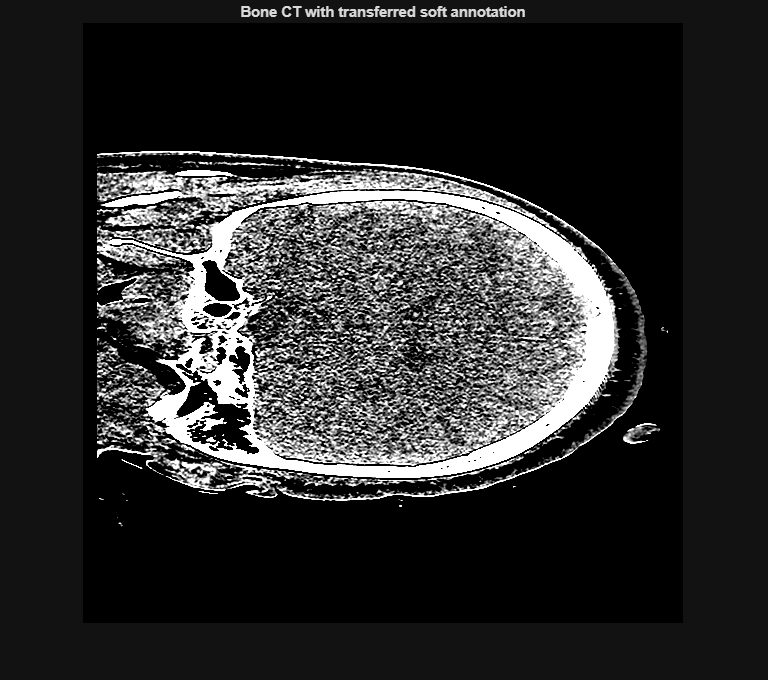

% --- settings ---
base_dir     = 'C:\Users\gdhan\Documents\tFUS';
volume_soft  = 'CT1_Soft';   % has CT1_Soft_target.mat inside this folder
volume_bone  = 'CT1_Bone';   % where the bone DICOMs (IMG*.dcm) live
FOV_mm       = [300 300 300]; % must match what you used when annotating soft

% 0) load the soft annotation + voxel_size that you used before
S = load(fullfile(base_dir, volume_soft, [volume_soft '_target.mat']), ...
         'target', 'voxel_size');
target_soft = S.target;
voxel_size  = S.voxel_size;   % reuse this voxel size

% 1) read bone DICOMs with your DicomToVolume (expects IMG00xx.dcm in CWD)
dicom_folder = fullfile(base_dir, volume_bone);
old_cwd = pwd; cd(dicom_folder);                 % important for your function
d = dir('IMG*.dcm');  % how many numbered slices you have
if isempty(d), error('No IMG*.dcm found in %s', dicom_folder); end
z_start = 1; z_end = numel(d); missing_slices = 0;

[~, ct_data_bone, voxel_spacing_bone] = DicomToVolume( ...
    dicom_folder, volume_bone, z_start, z_end, missing_slices, false);

cd(old_cwd);                                     % restore cwd

% 2) isotropic resample (skull not used; pass zeros)
[resized_CT_bone, ~, voxel_size_bone] = ...
    ResizeCT(ct_data_bone, zeros(size(ct_data_bone),'like',ct_data_bone), ...
             voxel_spacing_bone, volume_bone);

% 3) rebuild the same FOV cube (use the SAME voxel_size + FOV as soft)
[~, FOV_field_ct_bone] = PutIntoFOV(resized_CT_bone, ...
    zeros(size(resized_CT_bone),'like',resized_CT_bone), FOV_mm, voxel_size);

% 4) ensure mask dims match; resample if needed (nearest = label-safe)
if ~isequal(size(FOV_field_ct_bone), size(target_soft))
    target = imresize3(uint8(target_soft>0), size(FOV_field_ct_bone), 'nearest') > 0;
else
    target = target_soft;
end

% 5) quick visual check (mid sagittal)
midY = round(size(FOV_field_ct_bone,2)/2);
figure; imshow(squeeze(FOV_field_ct_bone(:,midY,:)), [0 100]); hold on;
contour(squeeze(target(:,midY,:)), [0.5 0.5], 'g', 'LineWidth', 1);
title('Bone CT with transferred soft annotation');


% 6) save next to the bone data (same pattern as soft)
save(fullfile(base_dir, volume_bone, [volume_bone '_target.mat']), ...
     'target', 'voxel_size', '-v7.3');
disp('✅ Saved CT1_Bone\CT1_Bone_target.mat (mask reused from soft).');

✅ Saved CT1_Bone\CT1_Bone_target.mat (mask reused from soft).


    %% --------------------------------------------------
    %% 30 × (Azimuth, Elevation) grid – clockwise around head
    %% --------------------------------------------------
    az_deg = 0 : 45 : 315;      % 8 azimuths: 0,45,90,…,315°
    el_deg = -40 : 20 : 40;       % 5 elevations: -40,-20,0,20,40°
    [AZ,EL] = meshgrid(az_deg,el_deg);
    az_list = AZ(:);              % 30×1
    el_list = EL(:);              % 30×1
    R_mm    = 100;                % 100 mm stand-off
    voxel_size = 0.6250;
    R_vox   = R_mm/voxel_size;    % convert to voxels
    
    % Define FOV and add skull to the enter
    FOV_X = 300; % mm
    FOV_Y = 300; % mm
    FOV_Z = 300; % mm
    FOV = [FOV_X, FOV_Y, FOV_Z];
    volDims = ceil(FOV/voxel_size);     % → [320 320 320]
    target     = false(volDims);                          % pre‐alloc your ROI mask
    
    % 1
    % After this call you get FOV_field_ct — your CT intensities sitting in a big blank cube
    % Load resized CT and skull
    volume_name = 'CT3_Bone';
    load(append(volume_name,'_resized_CT_data.mat'));
    
    [FOV_field_skull, FOV_field_ct] = PutIntoFOV(resized_CT, resized_skull, FOV, voxel_size);

    
    % Print confirmation message
    disp('✅ FOV_field_skull and FOV_field_ct successfully generated.');

✅ FOV_field_skull and FOV_field_ct successfully generated.


    fprintf('Size of FOV_field_ct: %s\n', mat2str(size(FOV_field_ct)));

Size of FOV_field_ct: [480 480 480]


    start = 225;
    stop = 275;
    figure;
    for i = start:stop
     % Open Dicom slice run through each file and select the field of interest
     % (DON'T HAVE TO DO THIS)
     I = squeeze(FOV_field_ct(:, i, :));
     img = imshow(I, [0,100]);
     view([-90,90]);
     % Draw ROI of Target
     roi = images.roi.AssistedFreehand(img);
     draw(roi)
     % Create mask and save ROI into volume
     target(:, i, :) = createMask(roi);
     % Show mask to confirm correct area
     imshow(squeeze(target(:, i, :)));
    end

Invalid or deleted object.

Error in images.roi.AssistedFreehand/createMask

    
    save('CT3_Bone_target.mat','target','voxel_size','-v7.3');
    disp('💾  Saved target volume to CT3_Bone_target.mat');

    % 2
    
    % Define transducer properties
    physical_radius = 100; % mm
    physical_diameter = 100; % mm
    
    % Convert transducer properties to grid points
    radius = round(physical_radius / voxel_size); % grid points
    diameter = round(physical_diameter / voxel_size); % grid points
    
    % Adjust diameter to be odd if it's even
    if mod(diameter, 2) == 0
     diameter = diameter - 1;
     display(append("Diameter was changed from: ", int2str(physical_diameter)," mm to: ",sprintf('%.2f',(diameter*voxel_size)), " mm"));
    end

    "Diameter was changed from: 100 mm to: 99.38 mm"



    
    % Get the transducer volume (tranducer_focal is the tranducer with a stick,
    % pointing to the focal stop)
    [transducer_1, transducer_focal_1, center_point_1] = BuildTransducer(radius, diameter);
    % [transducer_2, transducer_focal_2, center_point_2] = BuildTransducer(radius, diameter);

    p0 = [165,240,229];
    for idx = 1:numel(az_list)
      % 1) compute p1
      az = az_list(idx);  el = el_list(idx);
      p1 = round(p0 + R_vox * [cosd(el)*cosd(az),cosd(el)*sind(az),sind(el)]);
      
      % 2) minimal‐rotation from +Z→(p0–p1)
      v = (p0-p1)/norm(p0-p1);
      k = [0 0 1];
      if norm(cross(k,v))<eps
        Rmat = eye(3);
      else
        axis  = cross(k,v); axis=axis/norm(axis);
        angle = acos(dot(k,v));
        K     = [0   -axis(3)  axis(2);
                 axis(3)  0   -axis(1);
                -axis(2) axis(1)   0];
        Rmat  = eye(3) + sin(angle)*K + (1-cos(angle))*K*K;
      end
      eulXYZ_deg = rad2deg(rotm2eul(Rmat,'XYZ'));
    
      % 3) translate bowl centre to p1
      trans_vox = round(p1 - size(FOV_field_skull)/2);
    
      % 4) build & map the transducer
      [baseMask, baseFoc, ctr_local] = BuildTransducer(radius, diameter);
      [txMask{idx}, txFocal{idx}, ctr_out(idx,:)] = ...
        ApplyRotationAndTranslation(baseMask, baseFoc, ...
          eulXYZ_deg, trans_vox, FOV, voxel_size, ctr_local);
          rotList(idx,:) = eulXYZ_deg;   % <- add this line *inside* the loop
    
      disp(['✅ Bowl ' num2str(idx) ' mapped']);
    
    end

✅ Bowl 1 mapped
✅ Bowl 2 mapped
✅ Bowl 3 mapped
✅ Bowl 4 mapped
✅ Bowl 5 mapped
✅ Bowl 6 mapped
✅ Bowl 7 mapped
✅ Bowl 8 mapped
✅ Bowl 9 mapped
✅ Bowl 10 mapped
✅ Bowl 11 mapped
✅ Bowl 12 mapped
✅ Bowl 13 mapped
✅ Bowl 14 mapped
✅ Bowl 15 mapped
✅ Bowl 16 mapped
✅ Bowl 17 mapped
✅ Bowl 18 mapped
✅ Bowl 19 mapped
✅ Bowl 20 mapped
✅ Bowl 21 mapped
✅ Bowl 22 mapped
✅ Bowl 23 mapped
✅ Bowl 24 mapped
✅ Bowl 25 mapped
✅ Bowl 26 mapped
✅ Bowl 27 mapped
✅ Bowl 28 mapped
✅ Bowl 29 mapped
✅ Bowl 30 mapped
✅ Bowl 31 mapped
✅ Bowl 32 mapped
✅ Bowl 33 mapped
✅ Bowl 34 mapped
✅ Bowl 35 mapped
✅ Bowl 36 mapped
✅ Bowl 37 mapped
✅ Bowl 38 mapped
✅ Bowl 39 mapped
✅ Bowl 40 mapped


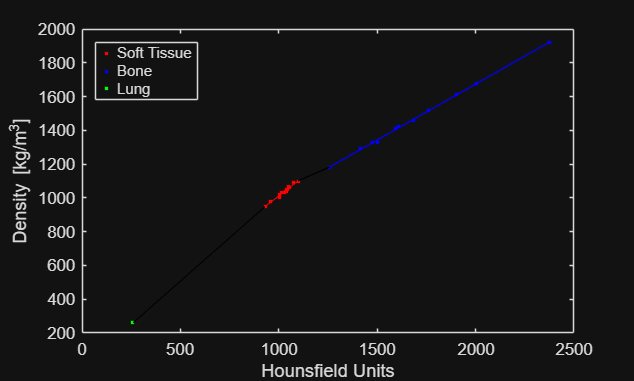

Running k-Wave simulation...
  start time: 23-Aug-2025 23:36:37
  reference sound speed: 3424.2023m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.8335s
  saving input files to disk...
  completed in 1.6045s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\train\CT\CT3_Bone_pose01_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose01_P.mat


Running k-Wave simulation...
  start time: 23-Aug-2025 23:40:06
  reference sound speed: 3208.3027m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 2.0416s
  saving input files to disk...
  completed in 1.2526s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\train\CT\CT3_Bone_pose02_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose02_P.mat


Running k-Wave simulation...
  start time: 23-Aug-2025 23:43:30
  reference sound speed: 3180.8516m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.7074s
  saving input files to disk...
  completed in 1.0005s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\test\CT\CT3_Bone_pose03_CT.mat


💾  Saved P  ► data\test\P\CT3_Bone_pose03_P.mat


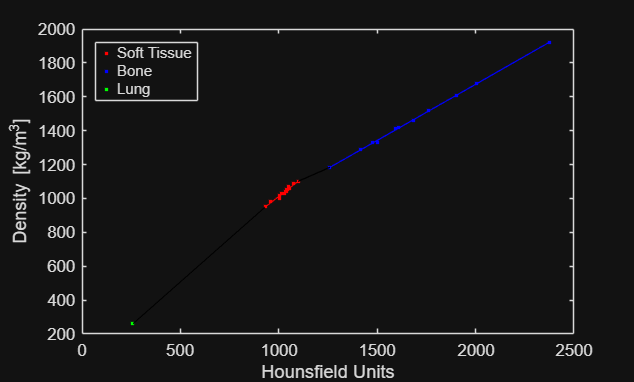

Running k-Wave simulation...
  start time: 23-Aug-2025 23:47:01
  reference sound speed: 3041.3701m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.6382s
  saving input files to disk...
  completed in 1.1438s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\train\CT\CT3_Bone_pose04_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose04_P.mat


Running k-Wave simulation...
  start time: 23-Aug-2025 23:50:30
  reference sound speed: 3094.7885m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.7152s
  saving input files to disk...
  completed in 1.1307s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\train\CT\CT3_Bone_pose05_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose05_P.mat


Running k-Wave simulation...
  start time: 23-Aug-2025 23:54:05
  reference sound speed: 3403.4284m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.7745s
  saving input files to disk...
  completed in 1.0652s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\test\CT\CT3_Bone_pose06_CT.mat


💾  Saved P  ► data\test\P\CT3_Bone_pose06_P.mat


Running k-Wave simulation...
  start time: 23-Aug-2025 23:57:31
  reference sound speed: 3059.9182m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.6991s
  saving input files to disk...
  completed in 1.2104s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\train\CT\CT3_Bone_pose07_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose07_P.mat


Running k-Wave simulation...
  start time: 24-Aug-2025 00:01:01
  reference sound speed: 2978.3067m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.7407s
  saving input files to disk...
  completed in 1.2382s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\train\CT\CT3_Bone_pose08_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose08_P.mat


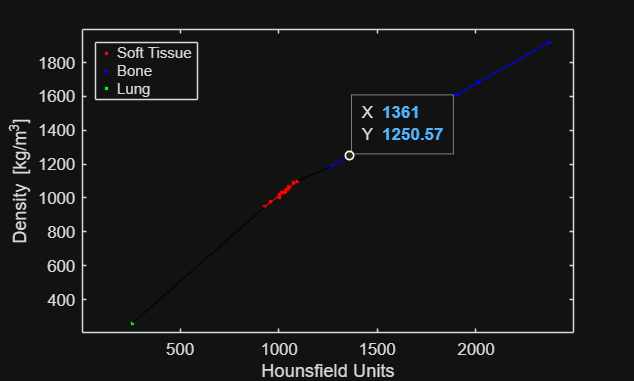

Running k-Wave simulation...
  start time: 24-Aug-2025 00:04:29
  reference sound speed: 3001.3063m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.6644s
  saving input files to disk...
  completed in 1.0579s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\train\CT\CT3_Bone_pose09_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose09_P.mat


Running k-Wave simulation...
  start time: 24-Aug-2025 00:07:59
  reference sound speed: 2993.887m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.7676s
  saving input files to disk...
  completed in 1.103s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+--------

💾  Saved CT ► data\train\CT\CT3_Bone_pose10_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose10_P.mat


Running k-Wave simulation...
  start time: 24-Aug-2025 00:11:24
  reference sound speed: 3035.4347m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.6503s
  saving input files to disk...
  completed in 1.0704s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\test\CT\CT3_Bone_pose11_CT.mat


💾  Saved P  ► data\test\P\CT3_Bone_pose11_P.mat


Running k-Wave simulation...
  start time: 24-Aug-2025 00:14:53
  reference sound speed: 2977.5647m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.7018s
  saving input files to disk...
  completed in 1.0931s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\train\CT\CT3_Bone_pose12_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose12_P.mat


Running k-Wave simulation...
  start time: 24-Aug-2025 00:18:32
  reference sound speed: 1669.3882m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.8954s
  saving input files to disk...
  completed in 1.0335s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\train\CT\CT3_Bone_pose13_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose13_P.mat


Running k-Wave simulation...
  start time: 24-Aug-2025 00:21:58
  reference sound speed: 2994.629m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.702s
  saving input files to disk...
  completed in 1.0355s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+--------

💾  Saved CT ► data\train\CT\CT3_Bone_pose14_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose14_P.mat


Running k-Wave simulation...
  start time: 24-Aug-2025 00:25:19
  reference sound speed: 3007.2416m/s
  dt: 41.6667ns, t_end: 199.9583us, time steps: 4800
  input grid size: 172 by 172 by 300 grid points (107.5 by 107.5 by 187.5mm)
  maximum supported frequency: 1.1908MHz
  expanding computational grid...
  computational grid size: 192 by 192 by 320 grid points
  precomputation completed in 1.7496s
  saving input files to disk...
  completed in 1.0203s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:           NVIDIA GeForce RTX 4060 Laptop GPU | 
| Number of CPU threads:                                      1 | 
| Processor name:                  Intel(R) Core(TM) i7-14650HX | 
+------

💾  Saved CT ► data\train\CT\CT3_Bone_pose15_CT.mat


💾  Saved P  ► data\train\P\CT3_Bone_pose15_P.mat


Error using generateDatasetCurrent>CutSimArea (line 541)
sim_transducer has no non-zero voxels.

    % create train/test directories once
    dirs = {'data/train/CT','data/train/P','data/test/CT','data/test/P'};
    for d = dirs, if ~exist(d{1},'dir'), mkdir(d{1}); end, end
    
    
    
    % Now loop over all 30 bowls:
    nPoses = numel(az_list);
    
    % --- define a fixed 30/10 train-test split ---
    assert(nPoses>=40,'Need at least 40 poses for test');
    
    rng(0);                  % for reproducibility
    perm     = randperm(nPoses);
    testIdx  = sort(perm(1:10));   % first 10 → test
    trainIdx = sort(perm(11:40));  % next 30 → train
    
    % make sure target is loaded once
    load('CT3_Bone_target.mat','target');
    
    for poseIdx = 1:nPoses
    
    
    % --- keep just ONE bowl -----------------------------------------------
    rotation = rotList(poseIdx,:);
    adjusted_transducer_1       = txMask{poseIdx};
    adjusted_transducer_focal_1 = txFocal{poseIdx};
    center_point_1              = ctr_out(poseIdx,:);
    % -----------------------------------------------------------------------
    
    % 5
    
    % Pick Transducer to Simulate and adjust rotation of skull to match 
    % Also cut down to defined window (currently diameter*1.5xfocal*2)
    [sim_transducer_precut_1, sim_transducerF_precut_1, sim_skull_precut_1, sim_ct_precut_1, sim_target_1, stats_1b, stats_1c] = PrepareSimField(center_point_1, ceil(adjusted_transducer_focal_1), ceil(adjusted_transducer_1), FOV_field_skull, FOV_field_ct, target, rotation);
    [sim_transducer_1, sim_transducerF_1, sim_skull_1, sim_ct_1, cut_start_1, cut_target_1] = CutSimArea(sim_transducer_precut_1, sim_transducerF_precut_1, sim_skull_precut_1, sim_ct_precut_1, sim_target_1);
    
    
    % 7
    
    % Prepare sim (parameters)
    
    freq = 25e4; % [Hz]
    mag = 6.19e4; % [Pa] 1.177e5 = 1.1e6 in water for 70mm 1.177e5 = 4.1856e6 in water for 100mm
    
    % Create the k-Wave medium structure
    inwater = false; % Replace
    
    temp = 22;
    
    % Define thresholds for segmentation
    bone_threshold = 260; % Threshold for bone in Hounsfield Units (HU)
    soft_tissue_threshold = -70; % Threshold for soft tissue in Hounsfield Units (HU)
    
    
    
    %% Tissue Properites from itis.swiss/virtual-population/tissue-properties
    % Attenuation
    aSkullCortical = 4.7384; % dB/(MHz^y cm) 13.63825 Np/m @ 250kHz
    aSkullCancellous = 4.0824; % dB/(MHz^y cm) 8.904834828248589 Np/m @ 250kHz
    aBrain = 0.5909; % dB/(MHz^y cm) 1.1221095273212693 Np/m @ 250kHz
    aWater = 0.0022; % dB/(MHz^y cm) 0.00633210900575 Np/m @ 250kHz
    
    % Prepare medium for sim
    % Create masks for different regions
    skull_mask_1 = sim_ct_1 > bone_threshold;
    soft_tissue_mask_1 = (sim_ct_1 > soft_tissue_threshold) & (sim_ct_1 <= bone_threshold);
    water_mask_1 = sim_ct_1 <= soft_tissue_threshold;
    
    % Create the alpha coefficient matrix
    alpha_coeff_1 = zeros(size(sim_ct_1));
    alpha_coeff_1(skull_mask_1) = aSkullCortical;
    alpha_coeff_1(soft_tissue_mask_1) = aBrain;
    alpha_coeff_1(water_mask_1) = aWater;
    
    % Use an average or dominant frequency power law exponent for the whole medium
    % For example, you might use an average value based on the expected proportions of each tissue type
    y_skull = 1.4; % Skull
    y_soft_tissue = 1.0; % Soft tissue
    y_water = 2.0; % Water
    
    % Convert CT image to density
    [density_cutoff_1, sound_speed_cutoff_1] = hounsfield2density(double(sim_ct_1)+1000, true);
    
    % Sound speed (water = waterSoundSpeed(temp))
    for x = 1:size(sound_speed_cutoff_1,1)
     for y = 1:size(sound_speed_cutoff_1,2)
     for z = 1:size(sound_speed_cutoff_1,3)
     if sound_speed_cutoff_1(x,y,z) < waterSoundSpeed(temp)
     sound_speed_cutoff_1(x,y,z) = waterSoundSpeed(temp);
     end
     end
     end
    end
    
    % Density (water = waterDensity(temp))
    for x = 1:size(density_cutoff_1,1)
     for y = 1:size(density_cutoff_1,2)
     for z = 1:size(density_cutoff_1,3)
     if density_cutoff_1(x,y,z) < waterDensity(temp)
     density_cutoff_1(x,y,z) = waterDensity(temp);
     end
     end
     end
    end
    
    
    % Define the k-Wave grid for sim
    Nx = size(sim_ct_1, 1); % number of grid points in the x direction
    Ny = size(sim_ct_1, 2); % number of grid points in the y direction
    Nz = size(sim_ct_1, 3); % number of grid points in the z direction
    dx = voxel_size * 1e-3; % grid point spacing in the x direction [mm]
    dy = voxel_size * 1e-3; % grid point spacing in the y direction [mm]
    dz = voxel_size * 1e-3; % grid point spacing in the z direction [mm]
    grid_size = [Nx, Ny, Nz]; % vector specifying grid size
    
    % Create the k-Wave grid
    kgrid = kWaveGrid(Nx, dx, Ny, dy, Nz, dz);
    
    if inwater
     medium_1.density = waterDensity(temp) * ones(Nx, Ny, Nz); % example density in kg/m^3
    
     medium_1.sound_speed = waterSoundSpeed(temp) * ones(Nx, Ny, Nz); % assuming a constant speed of sound of 1500 m/s
    
     medium_1.alpha_coeff = aWater; % Attenuation coefficient [Np/m]
     
     medium_1.alpha_power = y_water; % Use a scalar value for the power law exponent
    else 
     medium_1.density = density_cutoff_1;
    
     medium_1.sound_speed = sound_speed_cutoff_1;
    
     medium_1.alpha_coeff = alpha_coeff_1; % Attenuation coefficient [Np/m]
     
     medium_1.alpha_power = y_skull; % Use a scalar value for the power law exponent
    end
     
    % Define K-wave source
    % Define the source in terms of the transducer pressure
    % source_1.p_mask = makeBowl([Nx,Ny,Nz],[63,63,5],radius, diameter, [63,63,50]);
    % source_2.p_mask = makeBowl([Nx,Ny,Nz],[63,63,5],radius, diameter, [63,63,50]);
    
    
    source_1.p_mask = round(sim_transducer_1);
    
    % Calculate the time step using an integer number of points per period
    c0 = 1500; % speed of sound (min)
    ppw = c0 / (freq * dx); % points per wavelength
    % cfl number
    cfl = 0.1; % Replace 
    ppp = ceil(ppw / cfl); % points per period
    T = 1 / freq; % period [s]
    dt = T / ppp; % time step [s]
    
    % Define the total propagation time
    total_distance = 300e-3; % Replace
    total_time = total_distance / c0;
    
    % Set up the k-Wave time array
    Nt = round(total_time / dt);
    
    kgrid.setTime(Nt, dt);
    
    % Define a time-varying sinusoidal source
    source_freq = freq; % [Hz]
    source_mag = mag; % [Pa]
    source_1.p = source_mag * sin(2 * pi * source_freq * kgrid.t_array); % Define a sinusoidal pressure signal at 0.25 MHz
    % source_2.p = source_mag * sin(2 * pi * source_freq * kgrid.t_array); % Define a sinusoidal pressure signal at 0.25 MHz
    
    
    % Setup Sensor
    sensor.mask = ones(Nx, Ny, Nz); % all grid points as sensor points
    
    sensor.record = {'p_max_all'};
    % sensor.record_start_index = 4000;
    
    % Run Simulation
    % input arguments
    input_args = {'PlotLayout', true, 'PlotPML', true, 'PMLInside', false ...
     'DataCast', 'single', 'CartInterp', 'nearest'};
    
    % run the simulation
    sensor_data_1 = kspaceFirstOrder3DG(kgrid, medium_1, source_1, sensor, input_args{:});
    % 8
    
    % [Npoints, Ntimesteps] = size(sensor_data_1.p);   % <-- use what you got
    
    % sanity check: Npoints should equal Nx*Ny*Nz
    % assert(Npoints == Nx*Ny*Nz,      ...
           % 'Sensor mask is not full‑volume or Nx,Ny,Nz are wrong.');
    
    % Nx_eff = kgrid.Nx - 2*kgrid.PMLSize(1);
    % Ny_eff = kgrid.Ny - 2*kgrid.PMLSize(2);
    % Nz_eff = kgrid.Nz - 2*kgrid.PMLSize(3);
    
    % assert(Npoints == Nx_eff*Ny_eff*Nz_eff);
    
    % reshape with the true time dimension, not a magic 877
    % sensor_data_reshape_1 = reshape(sensor_data_1.p,[Nx,Ny,Nz,Ntimesteps]);
    
    % figure;
    % for t_index = 1:200
     % imagesc(squeeze(sensor_data_reshape_1(:, 62,:, t_index)));
     % colorbar;
     % set(gca, 'CLim', [-1e6, 1e6]);
     % hold on;
    
     % contour(squeeze(sim_skull_1(:, 62,:)),1,'LineColor', 'r', 'LineWidth', 2);
    
     % hold off;
     % pause(0.01);
    % end
    
    
    % max_press_1w = sensor_data_1.p_max_all; % max pressure field
    % focal_point_1 = [size(max_press_1w,1)/2, size(max_press_1w,2)/2, 2+(100/voxel_size)];
    
    
    
    % max_press_1 = sensor_data_1.p_max_all;
    % focal_point_1 = [size(max_press_1,1)/2, size(max_press_1,2)/2, 2+(100/voxel_size)];
    
    
    
    % PlotMaxPress(max_press_1w, sim_skull_1, sim_transducer_1, focal_point_1, false)
    
    
    % PlotMaxPress(max_press_1, sim_skull_1, source_1.p_mask, focal_point_1, true)
    
    
    % PlotMaxPress(max_press_2, sim_skull_2, source_2.p_mask, focal_point_2, true)
    
    
    
    % [focal_zone_1w] = PlotAlongFocus(max_press_1w, sim_skull_1, source_1.p_mask, focal_point_1, medium_1, cut_target_1);
    
    
    % [focal_zone_1] = PlotAlongFocus(max_press_1, sim_skull_1, source_1.p_mask, focal_point_1, medium_1, cut_target_1);
    
    
    % [focal_zone_2] = PlotAlongFocus(max_press_2, sim_skull_2, source_2.p_mask, focal_point_2, medium_2, cut_target_2);
    
    % [focal_zone_1w] = PlotAlongFocus(max_press_1w, sim_skull_1, source_1.p_mask, focal_point_1, medium_1, cut_target_1, voxel_size, inwater);
    % [focal_zone_1]  = PlotAlongFocus(max_press_1,  sim_skull_1, source_1.p_mask, focal_point_1, medium_1, cut_target_1, voxel_size, inwater);
    % [focal_zone_2]  = PlotAlongFocus(max_press_2,  sim_skull_2, source_2.p_mask, focal_point_2, medium_2, cut_target_2, voxel_size, inwater);
    
        if ~ismember(poseIdx, [trainIdx, testIdx])
            continue;
        end
    
        % pick base folder for train vs test
        if ismember(poseIdx, testIdx)
            base = 'data/test';
        else
            base = 'data/train';
        end
    
    % B.  -----------  save the CT‑side input ---------------------------------
    ct_file = fullfile(base,'CT', sprintf('%s_pose%02d_CT.mat', volume_name, poseIdx));
    
    targetSize = [100 100 160];
    origSize   = size(sim_ct_1);
    spacing_mm = (origSize .* voxel_size) ./ targetSize;
    
    % Resample inputs (linear for CT, nearest for masks)
    sim_ct_resized         = imresize3(sim_ct_1,           targetSize, 'linear');
    sim_skull_resized      = imresize3(sim_skull_1>0,      targetSize, 'nearest');
    sim_transducer_resized = imresize3(sim_transducer_1>0, targetSize, 'nearest');
    sim_target_resized     = imresize3(cut_target_1>0,     targetSize, 'nearest');
    
    % Resample label
    p_map_rs = imresize3(single(sensor_data_1.p_max_all), targetSize, 'linear');
    
    % ---- save CT pack ----
    ct_file = fullfile(base,'CT', sprintf('%s_pose%02d_CT.mat', volume_name, poseIdx));
    ct_struct = struct();
    ct_struct.ct            = single(sim_ct_resized);
    ct_struct.skull_mask    = uint8(sim_skull_resized);
    ct_struct.lens_mask     = uint8(sim_transducer_resized);
    ct_struct.target_mask   = uint8(sim_target_resized);
    ct_struct.spacing_mm    = spacing_mm;
    ct_struct.origin_vox    = cut_start_1;                 % optional
    ct_struct.origin_mm     = cut_start_1 .* voxel_size;   % optional
    ct_struct.already_resampled = true;                    % optional
    save(ct_file,'-struct','ct_struct','-v7.3');
    
    % ---- save P label ----
    p_file   = fullfile(base,'P',  sprintf('%s_pose%02d_P.mat', volume_name, poseIdx));
    p_struct = struct();
    p_struct.p_map          = p_map_rs;
    p_struct.spacing_mm     = spacing_mm;     % keep with label too
    p_struct.rotation_deg   = rotation;
    p_struct.center_point_1 = center_point_1;
    p_struct.freq           = freq;
    p_struct.source_mag     = mag;
    save(p_file,'-struct','p_struct','-v7.3');
    
    
    disp(['💾  Saved CT ► ' ct_file]);
    disp(['💾  Saved P  ► ' p_file]);
    end